**S.S.Hettiarachchi**

**180237G **

**BME**

# **Transfer Functions**

**Constructing Transfer funcction using MATLAB tf function**

let transfer function,


$$H\left(S\right)=\frac{20}{{3S}^2 +8S+20}$$


then,

 
$$\begin{array}{l}
\mathrm{Numerator}=20\\
\mathrm{Denominator}={3S}^2 +8S+20\;
\end{array}$$


num = 20;
den = [3 8 20];

use tf function,

H = tf(num,den);
display(H);


H =
 
         20
  ----------------
  3 s^2 + 8 s + 20
 
Continuous-time transfer function.



Plotting the** step response **

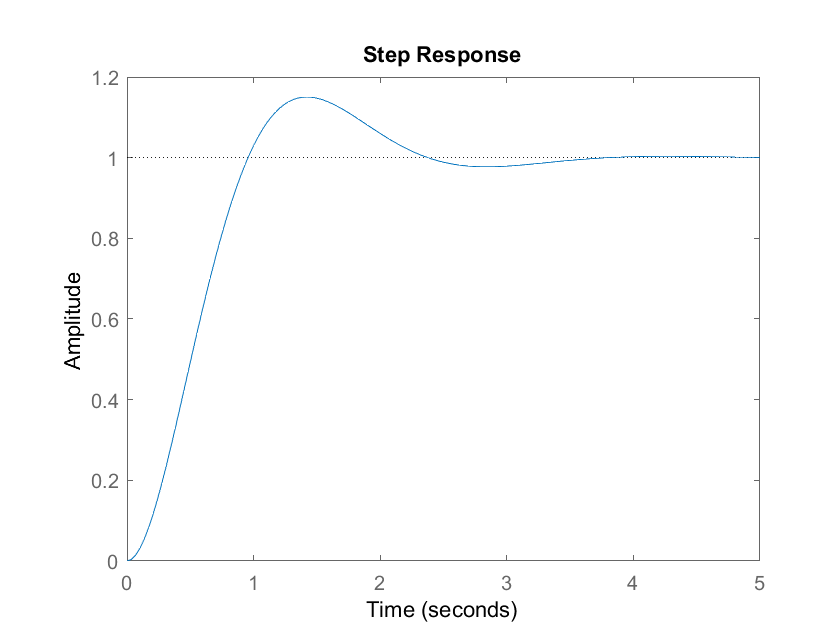

stepplot(H);

## Transfer function translation to factorizerd form

MATLAB **tf2zp **can be used to transform Transfer function to factored form

let $H\left(S\right)=\frac{11S^2 +88S+165}{S^3 +9S^2 +14S},$


$$H\left(S\right)=11\left(\frac{1S^2 +8S+15}{S^3 +9S^2 +14S}\right)$$



$$k=11$$



$$\mathrm{numerator}=$$

$$1S^2 +8S+15$$



$$\mathrm{denominator}=S^3 +9S^2 +14S$$


num1 = [1 8 15];
den1 = [1 9 14 0];

Transformation

[numZ,denP] = tf2zp(num1,den1);
display(numZ);

numZ =     -5
    -3


display(denP);

denP =      0
    -7
    -2


Therfore,


$$H\left(S\right)=\frac{11\left(S+5\right)\left(S+3\right)}{S\left(S+7\right)\left(S+2\right)}$$
